# MPC+KF tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end

gcp requires Parallel Computing Toolbox.

p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

## Define optimization variables

% lambda_z = optimizableVariable('lambda_z', [1e-4, 1e-2], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-3, 1e-1], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-2, 1], 'Transform', 'log');

% lambda_z = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-5, 1e-1], 'Transform', 'log');

lambda_z = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
lambda_o = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
lambda   = optimizableVariable('lambda'  , [1e-5, 1e-1], 'Transform', 'log');

optimization_variables = [lambda_z, lambda_o, lambda];
nVars = size(optimization_variables, 2);

## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = simulate(x);
    catch
        cost = 10;
    end
end

## Bayesian optimization

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |     lambda_z |     lambda_o |       lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       8 | Best   |     0.18843 |      253.85 |     0.18843 |     0.18843 |   0.00076268 |   6.6246e-05 |   0.00073094 |
|    2 |       2 | Accept |     0.32448 |      256.55 |     0.14501 |     0.14501 |     0.018828 |   0.00011293 |   2.3672e-05 |
|    3 |       2 | Accept |     0.45515 |      256.74 |     0.14501 |     0.14501 |    0.0094519 |   9.3873e-05 |   4.6465e-05 |
|    4 |    

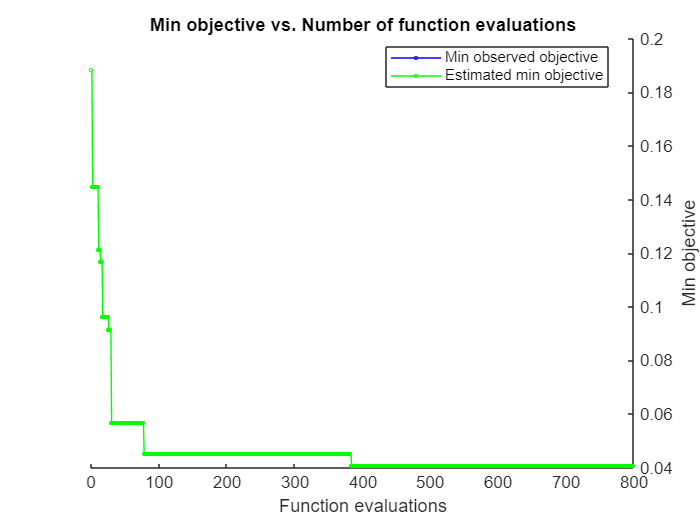

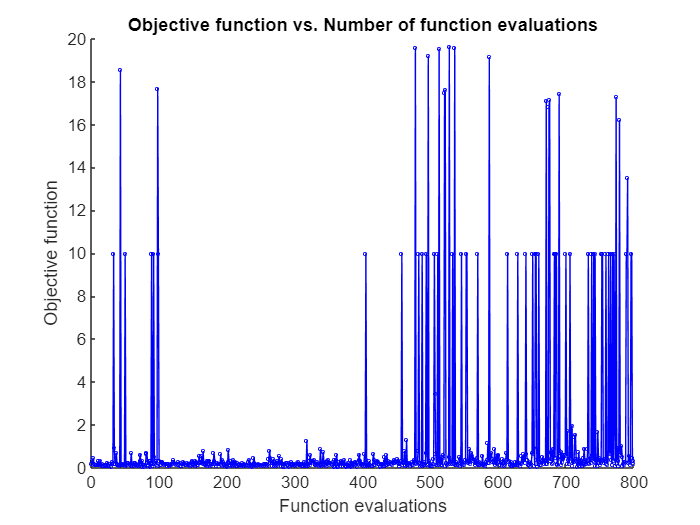

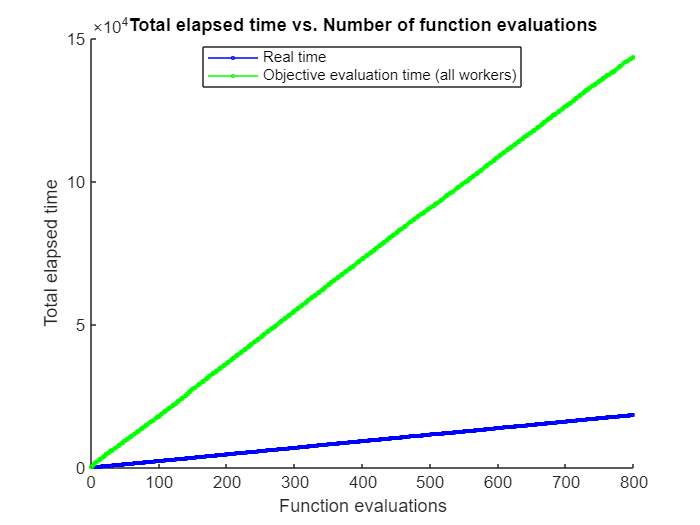

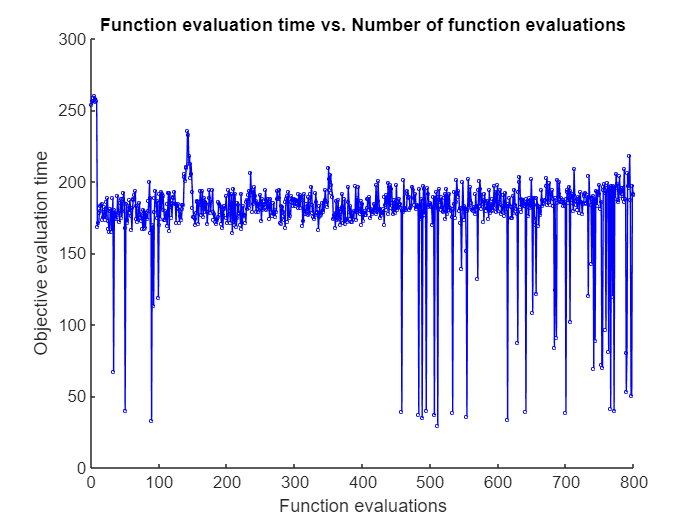

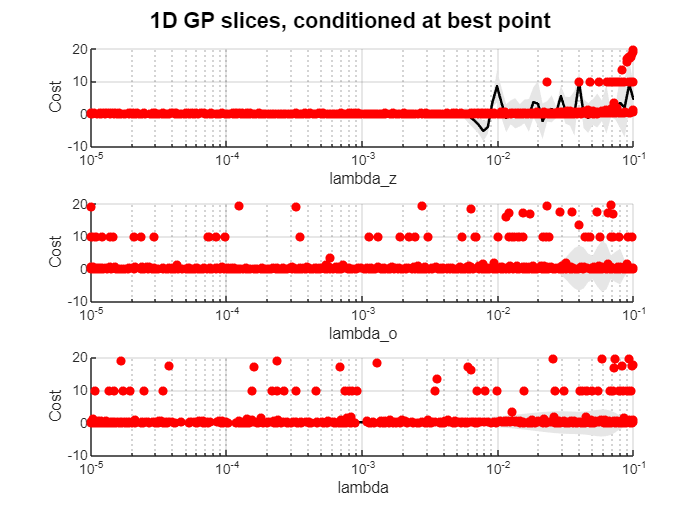

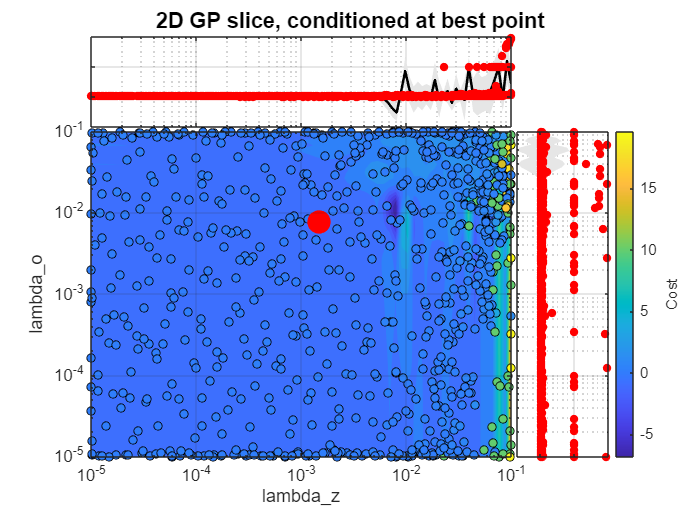


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 800 reached.
Total function evaluations: 800
Total elapsed time: 18537.0354 seconds
Total objective function evaluation time: 143741.9778

Best observed feasible point:
    lambda_z     lambda_o       lambda  
    _________    _________    __________
    0.0014797    0.0078478    1.1478e-05
Observed objective function value = 0.040829
Estimated objective function value = 0.040829
Function evaluation time = 172.1319

Best estimated feasible point (according to models):
    lambda_z     lambda_o       lambda  
    _________    _________    __________
    0.0014797    0.0078478    1.1478e-05
Estimated objective function value = 0.040829
Estimated function evaluation time = 180.40

NumSeedPoints = 2*p.NumWorkers;
lb = log10([1e-5, 1e-5, 1e-5]);
ub = log10([1e-1, 1e-1, 1e-1]);

Xlhs = lhsdesign(NumSeedPoints, nVars);
Xinit = 10 .^ bsxfun(@plus, lb, bsxfun(@times, (ub-lb), Xlhs));
Xinit = array2table(Xinit, 'VariableNames', {'lambda_z','lambda_o','lambda'});

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   10*p.NumWorkers, ...
    'InitialX',                  Xinit, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn',                   {@plotMinObjective, ...
                                  @plotObjective, ...
                                  @plotElapsedTime, ...
                                  @plotObjectiveEvaluationTime, ...
                                  @plotSurrogate} ...
);

## Reconstruct GP model

Retrieve bayesian optimization results

X = results.XTrace;
Y = results.ObjectiveTrace;
[Y, idx] = sort(Y, 'ascend'); % Sort by cost function
X = X(idx, :); 
varNames = {results.VariableDescriptions.Name};
sorted_Trace = [X table(Y, 'VariableNames', {'Cost'})]

sorted_Trace = 800×4 table
     lambda_z     lambda_o       lambda        Cost  
    __________    _________    __________    ________
     0.0014797    0.0078478    1.1478e-05    0.040829
     0.0011752    0.0085155     0.0002863    0.045059
      0.016079     0.057078     0.0068183    0.048783
      0.015443     0.048456    3.0626e-05     0.05203
    0.00086984    0.0093022    0.00030196    0.055421
     0.0010419    0.0053528    1.5093e-05     0.05646
      0.014048     0.077209    0.00018592      0.0568
    0.00066951    0.0073343    1.1012e-05    0.057272
    0.00035153    0.0028523     0.0011699     0.05776
     0.0025681     0.011543    1.1682e-05    0.058315
    0.00079612    0.0085651    1.1797e-05    0.059339
      0.019337     0.050587    1.6468e-05    0.060207
    0.00069056    0.0044359    0.00064014     0.06277
      0.011589     0.095331

Fit gaussian process

gp = fitrgp(X, Y, ...
    'Standardize', true, ...
    'KernelFunction', 'ardsquaredexponential');

## Plot GP

Plot fitted gaussian process

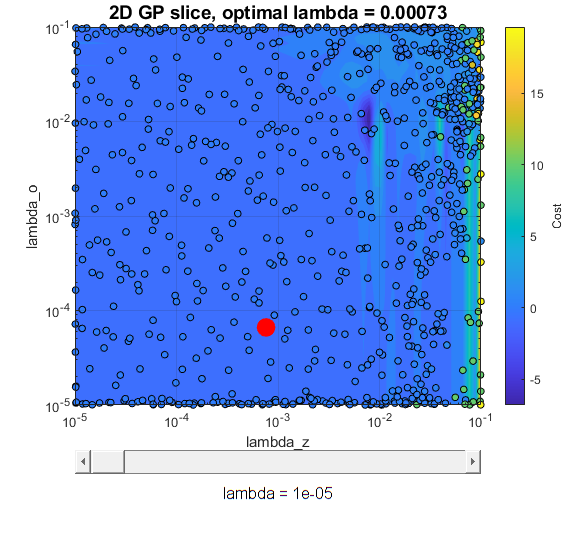

plotGP(gp, results)

## Sensitivity analysis

Global (trained kernel length scales)

lengthScales = gpGlobalSensitivity(gp)

lengthScales =     0.0326    0.2240    0.5883


Local (model gradient)

x_eval = table2array(X(1, :));
[gradMu, gradSigma2] = gpLocalSensitivity(gp, x_eval)

gradMu =    21.0497   -0.1923    1.0962


gradSigma2 =     0.0016    0.0008   -0.0004
